# 2. Segment capillaries in an microangiogram image.

Dock figure(1) for [this layout](https://docs.google.com/document/d/1RuEO2t5K-t82QPUK-sShLjorJyRC5uLGxchojfOiYDs/edit#heading=h.3m49wo5vra7y) **BEFORE** you run the first Section, and clear all output (View > Clear all Output).  

## 20. Initiate and load.

Select the microangio data to segment capillaries.  Ignore warning messages (orange color).

- aid = Analysis ID : The result from this analysis will be saved with `aid`. If you choose an existing `aid`, then you will be asked to load it. 

comInit;

uid = 'kwalek';  % User ID
eid = '180122_AD6';  % Expriment ID
pid = 'AD6_wk30_mangio1';  % Data ID

aid = 'AD6-wk30-mangio1-sc';  % Analysis ID

pathdata = ['D:\' uid '\' eid '\']; % path to save analysis data
pathrepo = ['\\files.brown.edu\Research\ENG_Lee-Lab_Shared\group\report\ad-16-ko-mouse\Microangiogram\2 Segment capillary # ' uid ' # ' aid ' # '];  % path of report figures

sec20;

nvexc = 1
medfsize = [3 3 3]
gaufsize = [5 5 5]
INIT COMPLETED.


## 21. Browse face slices and crop the volume when needed.

Set parameters and run this section.  The values in the instruction are default values.

*It is recommended to quit at the depth where you can see clear capillaries as many as possible.*

- diz = 3  :  Z-step to use in navigating en face slices.

- limDr = [.01 .85]  :  Color range of the angiogram images (relative on max)

UI keys:

- Q:  Quit

- D/E:  Move the next/previous depth.

SECTION 21 RUNNING ...


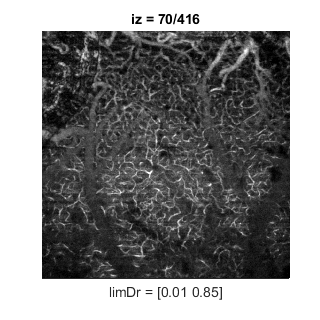

SECTION 21 COMPLETED.


diz = 3;
limDr = [.01 .85];

sec21;

### 21a. Crop the depth. 

Select the bottom depth below which you don't see additional *significant *capillaries.

Parameters

- DR = 0 : Dynamic range for the initial guess (nz1 s.t. Dz(nz1) = max(Dz)/DR).  If DR=0, nz1 at max(Dz).

- dnz1 = 10 : Pixel number to move the bottom depth

UI keys

- Q: Quit

- S/F: Move the bottom depth 

- G: Select the bottom depth manually.

Suggested action:

- Set DR = 0 and run the section.

- Press F key and see how many capillares are additinally visualized.

- Repeat 2 until there is no "significant" additional capillary.

- Use S/F key to make sure.

- Press Q key.

SECTION 21a RUNNING ...


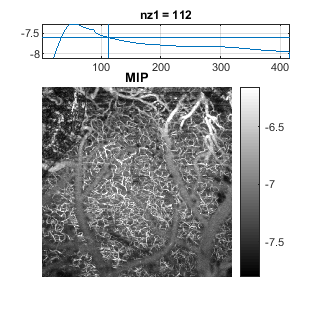

SECTION 21a COMPLETED.


DR = 0;
dnz1 = 10;

sec21a;

### 21b. Crop X and Y.

We will crop the volume using a square centered at the FOV. 

- nx1 = nx/2  :  The size of the cropping square.  Use a multiple of 8.  The default is to match the squre to the FOV of RBC data?

SECTION 21b RUNNING ...


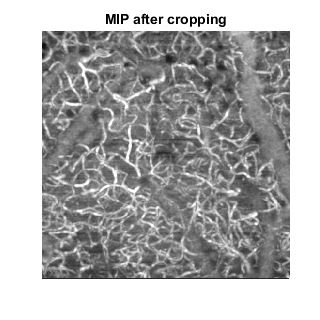

SECTION 21b COMPLETED.


nx1 = nx/2;

sec21b;

## 22. Enhance the image.

### Check points

- II map: Does the 3D FOV involve the whole spehroids, especially their top and bottom surfaces?     

- DD map: Do the spheroids exhibit larger DD values than background?     

- *Add your note here if any: .*

## 23. Set 3D ellipsoidal ROIs for spheroids.

You can ignore warning message (in orange color).  

If you loaded the existing data:

- If you simply want to re-analyze the statistics, skip this section.  

- If you want to re-set ROIs, change the value *ns *to the existing value (you can see the in the Workspace).

- If you want to re-set ROIs with different *ns*, execute *clear ccp* and run this section.

Parameters:

- ns = 16 : Number of spheroids to trace. When you change this value to reset the ROIs, execute *clear ccp* in the command window.  

- rx0 = 18 : Initial guess for lateral *radius* [voxel]. You can test how this initial guess is close to your spheroids in the image by comparing the initial circile in the *max I *figure to a spheroid. **If the automatic suggestion consistently give you larger or smaller diameters of the ROI, change this initial guess and rerun the curren section after executing *****clear ccp*****.**

- bRfix = false : Fix the ROI size to what you chose in the initial dataset (the first *did*)?

- dz = 3.5 : OCT system's axial sampling interval [um]

- limI = [.10 .99] : Color range for the intensity map (relative)

- limD = [.10 .99] : Color range for decorrelation maps (relative)

UI keys:

- Q: Quit

- V/X: Move to the next/previous spheroid.

- A/Z: Move to the next/previous dataset.

- G: Select the center of a spheroid.

- S/F: Move the ROI center in X axis.

- E/D: Move the ROI center in Y axis.

- W/R: Change the XY radius of ROI.

- I/K: Move the ROI center in Z axis.

- U/J: Change the Z radius of ROI.

Recommended action sequence:

- Push G, select the center in the "Max I" figure; and then select the center in the X-Z image. Adjust the ROI using I/K, U/J, S/F, E/D, and W/R keys.

- Push A to move on to the next dataset and repeat (1) to select the same spheroid.

- Once done for all datasets, push Z to go back to the first dataset and then push V to move on to the next spheroid. Repeat (1-3).

- Use V/X and A/Z keys to freely navigate and adjust ROIs between spheroids and datasets.

ns = 16;
rx0 = 18;
bRfix = false;
dz = 3.5;
limI = [.1 .99];
limD = [.1 .99];

sec23;

## 24. Analyze intensity and decorrelation.

I and D values are multiplied by 1e8.

Parameters:

- tt : The measurement time of each *did* [min]

- id0 = 1 : The index of of the baseline dataset for t-test (usually, "before treatment" or the first time point)

- rcore = 0.5 : Ratio of the *core* radius to spheroid radius

- (not used) rnn = 1.361/1.330 : Ratio of the refactive index of the treated medium (default = etOH) to that of background medium

tt = [10 20 30 40];
id0 = 1;
rcore = 0.5;
% rnn = 1.361/1.330;

sec24;

## 25. Analyze normalized decorreleation: Log fit

The decorrelation tends to increase when the intensity increases, and its relation looks like a log funciton. Without uncoupling the decorrelation from the intensity, an observed change in the decorrelation might be mainly affected by the corresponding change in the intensity.

Here, this section multiplies 10^8 to both *D *and *I*, and fits bin-averaged data to *D* = *a* * log( *I *+ *b* ) + *c* . The output variables are below, with physical implications. The implications are just my first glance, so some of them might be wrong -- let us take a look at the final statistical data and determine the impliactions and how they relate to cell death.

- The coefficient *a* (variable *logA*) represents how fast the decorrelation increases when the intensity increases; thus it may represent the intra-cellular motiltiy (ICM) regardless of how large the intensity values were. 

- The coefficient *b* (variable *logB*) is more related to the start point of the log function in the negative *I* region - its physical meaning is unclear yet. The same to the coefficient *c* (variable *logC*). 

- However, when combined with the coefficient *a*, they returns *D*(*I*=0) (variable *logD0*), which may represent the system's baseline noise (i.e., the hypothetical decorrelation level when the intensity is asymptotically zero).

- NDmean and NDstd [ns nd 3]: The mean and standard deviation of normalized decorrelation values over All (1), Core (2), and Shell (3 of the third dimension). The last errorbar in the figure below presents the COV (std/mean) of the region "All" since it can represent the image's heterogeneity and healthy spheroids may have higher heterogeneity (COV) as the cell membrane is normal and confines ICM within its inside. As can be seen in the errorbar in the second from the last, after normalization, changes in the decorrlation may become negligible (<5%).

Whenever you run this section with different** [oROI oBin fitid0]**, this section will save the result to a separate file with the suffix to *pathrepo*.

Parameters

- **oROI** = 1 : 1 = Use the ellipsoidal ROIs as chosen above.  2 = Use a cubic ROI including the surrounding medium voxels (to test how the result from this section is sensitive to the selection of ROIs).

- **oBin** = 2 : How to bin the D and I data.  1 = Same # voxels (*nvbin *below).  2 = Same interval in log.  3 = Same interval in linear.

- **fitid0 **= 1 : Apply the log fit of T=id0 to the other data.  Use each fit for each data when *fitid0* = 0.

- nvbin = 1000 : # voxel per bin (only used when oBin = 1)

- nbin = 16 : # bins (only used when oBin = 2 and 3)

- figType = 1 : Show normalized decorrelation maps via MIP (1) or of the center en face slice (2).

- limND = [.1 .99] : The color range for normalized decorrelation.

Ewha: let's test [1 2 1], [2 2 1], and [1 1 1].

oROI = 1; 
oBin = 2; 
fitid0 = 1;
nvbin = 1000;
nbin = 16; 
figType = 1;
limND = [.1 .99];

sec25;

## 29. Save analysis.

if ~isempty(dir([pathdata '/' aid '.mat']))
    disp(['Overwriting Data ...']);
else 
    disp('Saving ...');
end
clear cDD cII gx gy gz r img DD II Dsph Isph Iroi Droi Dxy Ixy ND Dbac Ibac;  % cDD and cII will be loaded again.
save('-v7.3',[pathdata '/' aid '.mat']);
disp('Analysis Saved.');
disp(['Recommended report file name:' newline '2 Analyze decorrelation # ' uid ' # ' aid '.html']);

You may also want to export this analysis to a report in HTML. Run *Live Editor > Save > Export to HTML*.

**Please do *****not *****save report files under GitHub folders**. Recommened are:

- Space: *\\files.brown.edu\research\ENG_Lee-Lab_Shared\group\report\cvi-18-3d\Decorrelation and Geometry*

- You can copy the path of space and paste it into the export window.

- File name: printed above